# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.3 简单曲线之间填充

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

填充函数，fill、patch 都差不多，个人理解是填充一系列点构成的封闭区域（认为是个多边形区域也没毛病）；

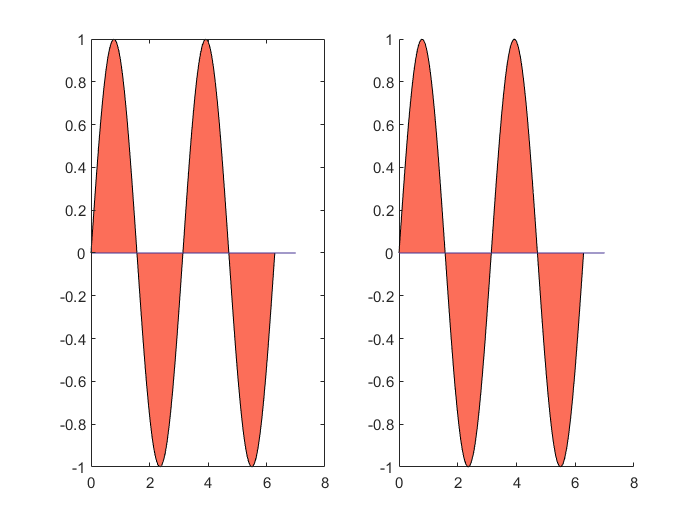

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 生成数据
x = linspace(0, 2*pi, 100);
y = sin(2*x);
figure
subplot(1, 2, 1)
fill(x, y, all_colors(1, :)); 
hold on
plot([0, 7], [0, 0], 'Color', all_colors(6, :));
hold off
subplot(1, 2, 2)
patch(x, y, all_colors(1, :)); 
hold on
plot([0, 7], [0, 0], 'Color', all_colors(6, :));
hold off

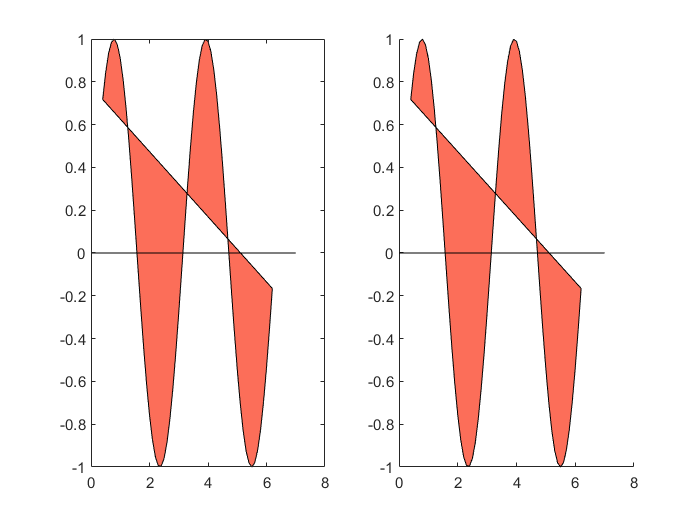

% 换一下数据
x = 0.4:0.1:2*pi;
y = sin(2*x);
figure
subplot(1, 2, 1)
fill(x, y, all_colors(1, :));
hold on
plot([0, 7], [0, 0], 'k');
hold off
subplot(1, 2, 2)
patch(x, y, all_colors(1, :)); 
hold on
plot([0, 7], [0, 0], 'k');
hold off

#### 这个结果似乎没有达到预期，查询到 fill 和 patch 函数是做的多边形填充，因此需要做一些修改。

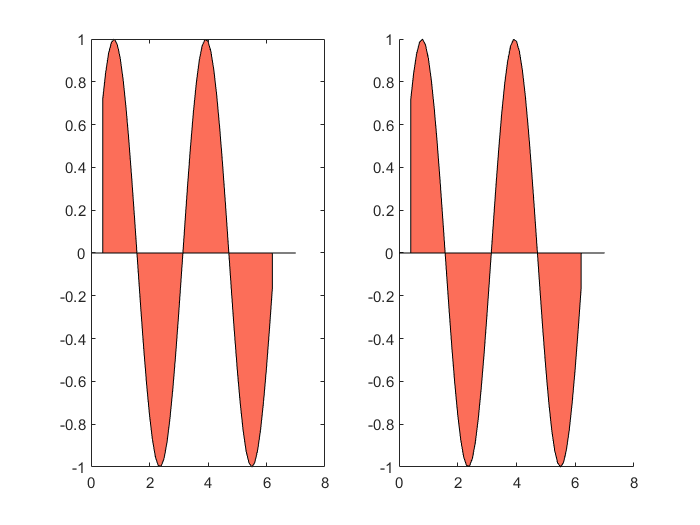

% 强制首尾各添加一个点，保证 y 值为 0
x = [x(1), x, x(end)];
y = [0, y, 0];
figure
subplot(1, 2, 1)
fill(x, y, all_colors(1, :));
hold on
plot([0, 7], [0, 0], 'k');
hold off
subplot(1, 2, 2)
patch(x, y, all_colors(1, :)); 
hold on
plot([0, 7], [0, 0], 'k');
hold off

#### 函数之间围成的区域填充演示：

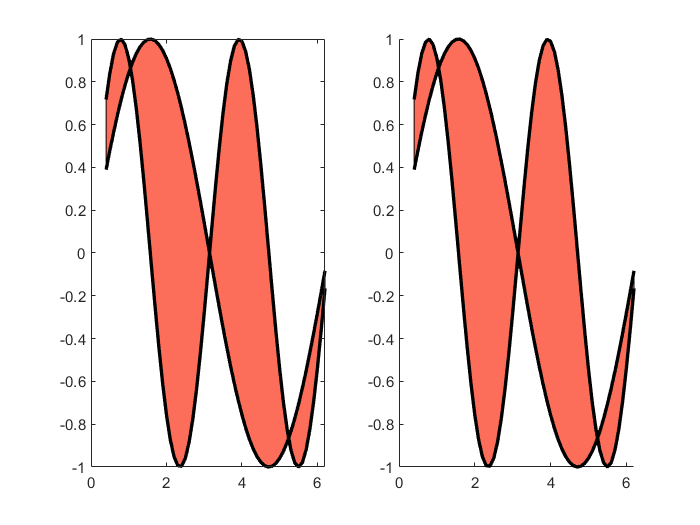

x = 0.4:0.1:2*pi;
y1 = sin(2*x);
y2 = sin(x);
% 确定 y2 和 y4 的上下边界
maxY = max([y1; y2]);
minY = min([y1; y2]);
% 确定填充多边形，按照顺时针方向来确定点
% fliplr 实现左右翻转
xFill = [x, fliplr(x)];
yFill = [maxY, fliplr(minY)];
figure
subplot(1, 2, 1)
fill(xFill, yFill, all_colors(1, :));
hold on
plot(x, y1, 'k', 'LineWidth', 2)
plot(x, y2, 'k', 'LineWidth', 2)
hold off
subplot(1, 2, 2)
patch(xFill, yFill, all_colors(1, :)); 
hold on
plot(x, y1, 'k', 'LineWidth', 2)
plot(x, y2, 'k', 'LineWidth', 2)
hold off